# コイン交換によるカノニカル分布の生成

clear all;
clf;

## コイン交換モデル

### 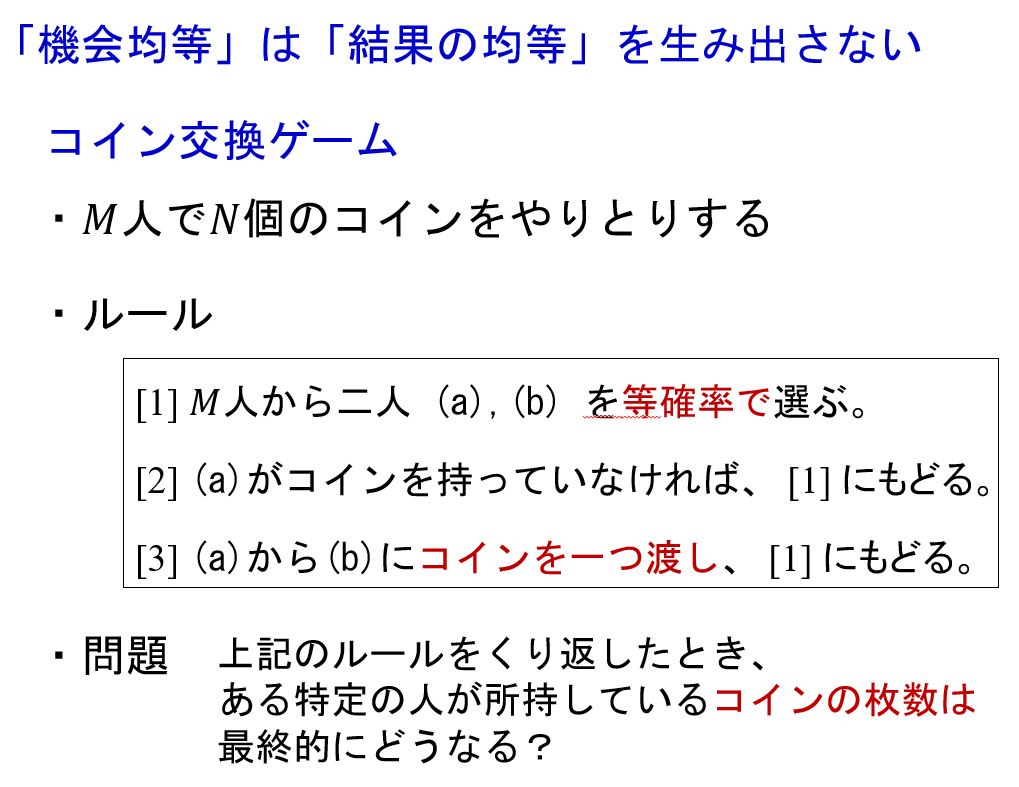

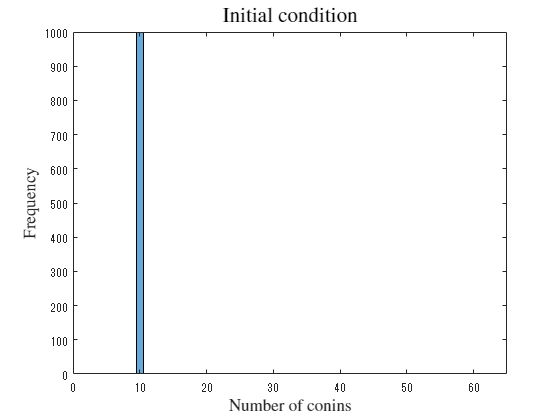

N = 10000; %コイン数
M = 1000; %人数

% initial condition
% 
xc = N/M*ones([1 M]);
histogram(xc)
xlim([0 65])

title("Initial condition", Interpreter="latex", FontSize=16)
xlabel('Number of conins', Interpreter='latex', FontSize=13)
ylabel('Frequency', Interpreter='latex', FontSize=13)

%exportgraphics(gca, 'Coin_exchange_000000.png')

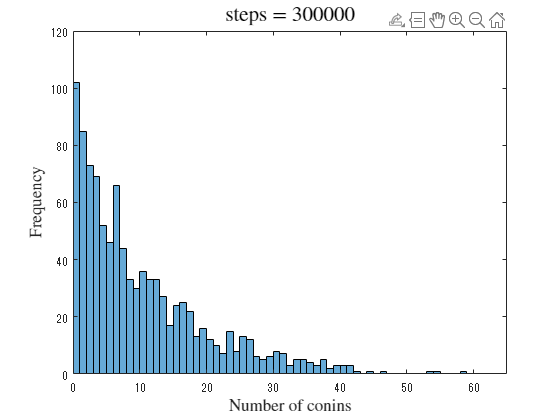


% maximum step
tm = 300001;
for j = 1:1:tm
    ps_chk = 0;
    while ps_chk == 0
        ps = randi([1 M],[1 2]);
        if (ps(1) ~= ps(2)) & (xc(ps(1)) > 0)
            ps_chk = 1;
        end
    end

    xc(ps(1)) = xc(ps(1)) - 1;
    xc(ps(2)) = xc(ps(2)) + 1;

    if ((j<00)&(rem(j, 10) == 0))||((j>=00)&(rem(j, 500) == 0))
        edges = [0:1:60];
        histogram(xc, edges)
    %     xlabel("velocity")
    %     ylabel("frequency")
        title("steps = "+string(j), Interpreter="latex", FontSize=16)
        xlabel('Number of conins', Interpreter='latex', FontSize=13)
        ylabel('Frequency', Interpreter='latex', FontSize=13)
        %ylim([0 1.1*M])
        xlim([0 65])
        drawnow
    end
    % if ((j==3000)||(j==30000)||(j==300000))
    %    exportgraphics(gca, 'Coin_exchange_'+string(j)+'.png')
    % end
end

edges2 = [0:2:60];
[hm1, edges2] = histcounts(xc, edges2);
hm1v = hm1;
hm1x = edges2(1:end-1)+0.5*(edges2(2)-edges2(1));

%% 近似: '新規近似 1'。
[xData, yData] = prepareCurveData( hm1x, hm1v );

% 近似タイプとオプションを設定します。
ft = fittype( 'exp1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [93.1500294644759 -0.0928478954905877];

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      一般モデル Exp1:
     fitresult(x) = a*exp(b*x)
     係数 (95% の信頼限界):
       a =       193.4  (180.9, 205.9)
       b =    -0.09784  (-0.1068, -0.08892)

gof = フィールドをもつ struct :
           sse: 1.2982e+03
       rsquare: 0.9794
           dfe: 28
    adjrsquare: 0.9787
          rmse: 6.8092


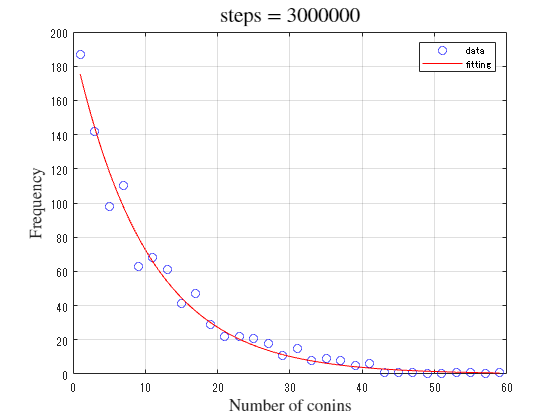


% データの近似をプロットします。
figure( 'Name', '新規近似 1' );
h = plot( fitresult, xData, yData, 'bo' );
legend( h, 'data', 'fitting', 'Location', 'NorthEast', 'Interpreter', 'none' );
% ラベル Axes
title("steps = 3000000", Interpreter="latex", FontSize=16)
xlabel('Number of conins', Interpreter='latex', FontSize=13)
ylabel('Frequency', Interpreter='latex', FontSize=13)

grid on
%exportgraphics(gca, 'Coin_exchange_3000000_fit.png')

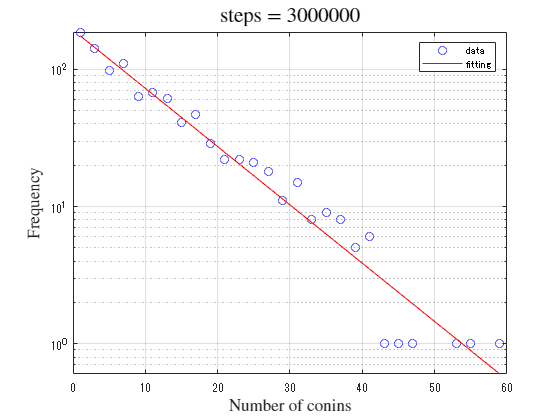

semilogy(hm1x, hm1, 'bo')
hold on
    semilogy(xData, fitresult(xData), 'r-')
    xlabel( 'coins', 'Interpreter', 'none' );
    ylabel( 'frequency', 'Interpreter', 'none' );
    legend( 'data', 'fitting', 'Location', 'NorthEast', 'Interpreter', 'none' );
    grid on
    
    title("steps = 3000000", Interpreter="latex", FontSize=16)
    xlabel('Number of conins', Interpreter='latex', FontSize=13)
    ylabel('Frequency', Interpreter='latex', FontSize=13)
    
hold off
%exportgraphics(gca, 'Coin_exchange_3000000_fit_sl.png')